cd 'C:\GitHub\CVUT-MatLab\grant'
startup

## Import JSON

Upozonění! Richard počítá od 0. Já v kódu začínám řadu 1. Tudíž všude kde přebírám nějaké indexy přičítám jedničku. 

import = jsonImportFn('DiscreteMechanicalModelExportModelML0-smaller.json');

## Sections

crossSectionsSet.import = importdata("sectionsSet.mat");
crossSectionsSet.A = cat(1, table2array(crossSectionsSet.import.RHS(:,"A")), table2array(crossSectionsSet.import.L(:,"A")));
crossSectionsSet.Iy = cat(1, table2array(crossSectionsSet.import.RHS(:,"Iy")), table2array(crossSectionsSet.import.L(:,"Iu")));
crossSectionsSet.Iz = cat(1, table2array(crossSectionsSet.import.RHS(:,"Iz")), table2array(crossSectionsSet.import.L(:,"Iv")));
crossSectionsSet.Ip = cat(1, table2array(crossSectionsSet.import.RHS(:,"Ip")), table2array(crossSectionsSet.import.L(:,"Ip")));

sections.id = ones(112,1)*9;            %pořadí určuje prut, hodnota určuje zvolený prut ze sady profilů

[s,~] = size(sections.id);
for j = 1:s
    sections.A(j,1)  = crossSectionsSet.A(sections.id(j));
    sections.Iy(j,1) = crossSectionsSet.Iy(sections.id(j));
    sections.Iz(j,1) = crossSectionsSet.Iz(sections.id(j));
    sections.Ix(j,1) = crossSectionsSet.Ip(sections.id(j));
    sections.E(j,1)  = 210*10^9;
    sections.v(j,1)  = 0.3;
end

ndisc = 7;          % počet elementů na prutu

## Nodes

nodes.x = import.Nodes(:,1);            % x coord of the nodes
nodes.y = import.Nodes(:,2);            % y coord of the nodes
nodes.z = import.Nodes(:,3);            % z coord of the nodes
nnodes = numel(nodes.x);                % number of nodes

## Supports

supportNodes = [import.NodalSupports.Node]'+1;
supportDirections = [import.NodalSupports.Fixed]';

kinematic.x.nodes   = supportNodes(supportDirections(:,1));     % node indices with restricted x-direction displacements
kinematic.y.nodes   = supportNodes(supportDirections(:,2));     % node indices with restricted y-direction displacements
kinematic.z.nodes   = supportNodes(supportDirections(:,3));     % node indices with restricted z-direction displacements
kinematic.rx.nodes  = supportNodes(supportDirections(:,4));     % node indices with restricted rx-direction displacements
kinematic.ry.nodes  = supportNodes(supportDirections(:,5));     % node indices with restricted ry-direction displacements
kinematic.rz.nodes  = supportNodes(supportDirections(:,6));     % node indices with restricted rz-direction displacements

nodes.dofs = true(nnodes,6);                    % no kinematic boundary conditions
nodes.dofs(kinematic.x.nodes,1)     = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.y.nodes,2)     = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.z.nodes,3)     = false;    % mark prevented movement in z-direction
nodes.dofs(kinematic.rx.nodes,4)    = false;    % mark prevented movement in rx-direction
nodes.dofs(kinematic.ry.nodes,5)    = false;    % mark prevented movement in ry-direction
nodes.dofs(kinematic.rz.nodes,6)    = false;    % mark prevented movement in rz-direction

## Beams

beams.nodesHead = [import.FrameElements.HeadNode]'+1;           % id of starting nodes
beams.nodesEnd = [import.FrameElements.EndNode]'+1;
nr = numel(beams.nodesHead);

### Beams sections

beams.disc      = ones(nr,1)*ndisc;
beams.sections = [import.FrameElements.SectionIndex]'+1;

#### Vykreslení konstrukce - lze vymazat

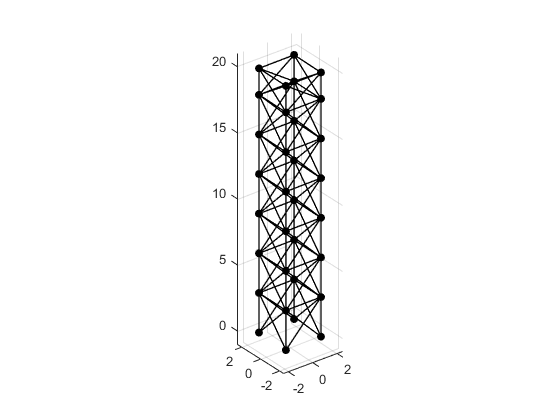

plot3([nodes.x(beams.nodesHead) nodes.x(beams.nodesEnd)]', ...
     [nodes.y(beams.nodesHead) nodes.y(beams.nodesEnd)]', ...
     [nodes.z(beams.nodesHead) nodes.z(beams.nodesEnd)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'black', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on
hold off

## Loads

nLoads = size([import.LoadCases],1);        %Number of Load cases
loads.x.nodes = [];             % node indices with x-direction forces
loads.y.nodes = [];             % node indices with y-direction forces
loads.z.nodes = [];             % node indices with z-direction forces
loads.x.value = [];             % magnitude of the x-direction forces
loads.y.value = [];             % magnitude of the y-direction forces
loads.z.value = [];             % magnitude of the z-direction forces

for i = 1:nLoads
    loadNodes = [import.LoadCases(i).NodalForces.Node]'+1;
    loadForces = [import.LoadCases(i).NodalForces.F]';
    loadCond = loadForces ~= 0;
    loads.x.nodes = [loads.x.nodes ; loadNodes(loadCond(:,1))];             % node indices with x-direction forces
    loads.y.nodes = [loads.y.nodes ; loadNodes(loadCond(:,2))];             % node indices with y-direction forces
    loads.z.nodes = [loads.z.nodes ; loadNodes(loadCond(:,3))];             % node indices with z-direction forces
    loads.x.value = [loads.x.value ; loadForces(loadCond(:,1), 1)];         % magnitude of the x-direction forces
    loads.y.value = [loads.y.value ; loadForces(loadCond(:,2), 2)];         % magnitude of the y-direction forces
    loads.z.value = [loads.z.value ; loadForces(loadCond(:,3), 3)];         % magnitude of the z-direction forces
end

loads.rx.nodes = [];          % node indices with x-direction forces
loads.rx.value = [];          % magnitude of the x-direction forces
loads.ry.nodes = [];          % node indices with y-direction forces
loads.ry.value = [];          % magnitude of the y-direction forces 
loads.rz.nodes = [];          % node indices with z-direction forces
loads.rz.value = []; 

## Force vector

forceVector = sparse([loads.x.nodes*6-5; loads.y.nodes*6-4; loads.z.nodes*6-3;loads.rx.nodes*3-2; loads.ry.nodes*3-1; loads.rz.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value;loads.rx.value; loads.ry.value; loads.rz.value], ...
                     nnodes*6, 1);
f = forceVector(reshape(reshape(nodes.dofs.',[],1).', 1, [])');     %Pravá strana vektor f

## FEM

nodes.ndofs = sum(sum(nodes.dofs));
nodes.nnodes    = nnodes;
localZ = [import.FrameElements.LocalZ]';

beams.nbeams  = nr;
beams.vertex = beamVertexFn(beams,nodes);
beams.codeNumbers = codeNumbersFn(beams,nodes);
beams.XY = ZtoBeamsFn(beams,localZ);

elements = discretizationBeamsFn(beams,nodes);
elements.XY = XYtoElementFn(beams);
elements.sections = sectionToElementFn(sections,beams);
elements.ndofs = max(max(elements.codeNumbers));


### Linear analysis

endForces.global = sparse(elements.ndofs,1);
endForces.global(1:max(max(beams.codeNumbers))) = f;

transformationMatrix = transformationMatrixFn(elements);

stiffnesMatrix = stiffnessMatrixFn(elements,transformationMatrix);

[endForces.local,~] = endForcesFn(stiffnesMatrix,endForces,transformationMatrix,elements);

### Non-linear analysis

geometricMatrix = geometricMatrixFnV2(elements,transformationMatrix,endForces);

% volume = sum(elements.sections.A .* transformationMatrix.lengths)

Results = criticalLoadFn(stiffnesMatrix,geometricMatrix,10);

[sortedValues,sortedVectors]= sortValuesVectorFn(Results.values,Results.vectors);

disp('1. kritické břemeno');

1. kritické břemeno


disp([num2str(sortedValues(1)),' N']);

15.8614 N


disp('2. kritické břemeno');

2. kritické břemeno


disp([num2str(sortedValues(2)),' N']);

16.7627 N


disp('3. kritické břemeno');

3. kritické břemeno


disp([num2str(sortedValues(3)),' N']);

-18.1977 N


disp('4. kritické břemeno');

4. kritické břemeno


disp([num2str(sortedValues(4)),' N']);

18.2196 N


disp('5. kritické břemeno');

5. kritické břemeno


disp([num2str(sortedValues(5)),' N']);

18.2543 N


disp('6. kritické břemeno');

6. kritické břemeno


disp([num2str(sortedValues(6)),' N']);

-19.2904 N


disp('7. kritické břemeno');

7. kritické břemeno


disp([num2str(sortedValues(7)),' N']);

-20.8526 N


disp('8. kritické břemeno');

8. kritické břemeno


disp([num2str(sortedValues(8)),' N']);

-21.0017 N


disp('9. kritické břemeno');

9. kritické břemeno


disp([num2str(sortedValues(9)),' N']);

23.8463 N


disp('10. kritické břemeno');

10. kritické břemeno


disp([num2str(sortedValues(10)),' N']);

24.2591 N


sections.id;